Testul 1 - Balahura Vlad - grupa 231/1

**Problema 1. **Sa se analizeze metoda lui Cramer si eliminarea gaussiana din punct de vedere al complexitatii (unitatea de masura va fi numarul de operatii flotante - flops) ın cazurile n = 2 ¸si n = 3

Analiza complexității, exprimată în numărul de operații flotante (flops), relevă o diferență fundamentală de eficiență computațională între Eliminarea Gaussiană și Metoda lui Cramer. Analizând cazurile specifice cerute, observăm că pentru $$n = 2$$ costul computațional este aproape identic, ambele metode fiind la fel de viabile, cu 10 flops pentru Gauss și 11 flops pentru Cramer. Totuși, divergența devine evidentă imediat ce trecem la n=3, unde metoda Cramer devine de peste două ori mai costisitoare, necesitând 75 de operații flotante comparativ cu doar 30 în cazul Eliminării Gaussiene. Această diferență uriașă de scalabilitate este explicată de ordinele de complexitate asimptotică ale celor doi algoritmi. Metoda lui Cramer, fiind implementată prin calculul recursiv al determinanților, necesită rezolvarea a $$n+1$$ determinanți, rezultând o complexitate asimptotică factorială de ordinul $$\mathcal{O}((n+1)!)$$, o creștere explozivă care o face practic imposibil de rulat chiar și pentru sisteme de dimensiuni medii. Pe de altă parte, Eliminarea Gaussiană scalează mult mai blând, având un cost computațional polinomial cu o complexitate cubică de ordinul $$\mathcal{O}(n^3)$$. În concluzie, deși ambele metode sunt corecte din punct de vedere teoretic, Eliminarea Gaussiană confirmă o eficiență computațională net superioară odată cu creșterea dimensiunii sistemului, motiv pentru care este standardul utilizat în rezolvarea practică a sistemelor de ecuații liniare.

n = 2;
A = rand(n, n);
b = rand(n, 1);

[x_gauss, f_gauss2] = gauss_flops(A, b);
[x_cramer, f_cramer2] = cramer_flops(A, b);

fprintf('Sistem n=%d | Gauss flops: %d | Cramer flops: %d\n', n, f_gauss2, f_cramer2);

Sistem n=2 | Gauss flops: 10 | Cramer flops: 11



n = 3;
A = rand(n, n);
b = rand(n, 1);

[x_gauss, f_gauss3] = gauss_flops(A, b);
[x_cramer, f_cramer3] = cramer_flops(A, b);

fprintf('Sistem n=%d | Gauss flops: %d | Cramer flops: %d\n', n, f_gauss3, f_cramer3);

Sistem n=3 | Gauss flops: 30 | Cramer flops: 75




n = 4;
A = rand(n, n);
b = rand(n, 1);

[x_gauss, f_gauss4] = gauss_flops(A, b);
[x_cramer, f_cramer4] = cramer_flops(A, b);

fprintf('Sistem n=%d | Gauss flops: %d | Cramer flops: %d\n', n, f_gauss4, f_cramer4);

Sistem n=4 | Gauss flops: 65 | Cramer flops: 424


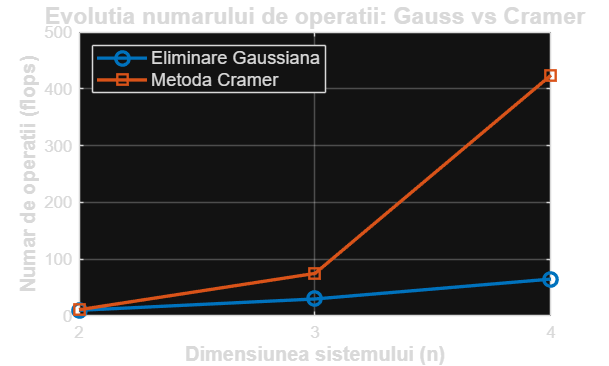



vector_n = [2, 3, 4];
vector_gauss = [f_gauss2, f_gauss3, f_gauss4];
vector_cramer = [f_cramer2, f_cramer3, f_cramer4];

figure('Name', 'Comparatie Complexitate', 'Color', 'w');

plot(vector_n, vector_gauss, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410]); % Albastru pt Gauss
hold on;
plot(vector_n, vector_cramer, '-s', 'LineWidth', 2, 'MarkerSize', 8, 'Color', [0.8500 0.3250 0.0980]); % Portocaliu/Rosu pt Cramer


xlabel('Dimensiunea sistemului (n)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Numar de operatii (flops)', 'FontSize', 12, 'FontWeight', 'bold');
title('Evolutia numarului de operatii: Gauss vs Cramer', 'FontSize', 14);
xticks(2:1:4); 
grid on;       
legend('Eliminare Gaussiana', 'Metoda Cramer', 'Location', 'northwest', 'FontSize', 11);

hold off;

Am implementat metoda lui Cramer si eiminarea Gausiana impreuna cu un contor pentru fiecare, care masoara numerul de operatii flotante.


function [x, flops] = gauss_flops(A, b)

    n = length(b);
    flops = 0; 
    A_ext = [A, b(:)];
    
    for i = 1:n-1
        for j = i+1:n
          
            m = A_ext(j, i) / A_ext(i, i);
            flops = flops + 1; 
            
            for k = i+1:n+1
             
                A_ext(j, k) = A_ext(j, k) - m * A_ext(i, k);
                flops = flops + 2; 
            end
        end
    end
    

    x = zeros(n, 1);
    
   
    x(n) = A_ext(n, n+1) / A_ext(n, n);
    flops = flops + 1;
    
    for i = n-1:-1:1
        suma = 0;
        for j = i+1:n

            suma = suma + A_ext(i, j) * x(j);
            flops = flops + 2;
        end

        x(i) = (A_ext(i, n+1) - suma) / A_ext(i, i);
        flops = flops + 2;
    end
end

function [x, flops] = cramer_flops(A, b)

    n = length(b);
    flops = 0;
    x = zeros(n, 1);
    

    [detA, flops_detA] = det_recursiv(A);
    flops = flops + flops_detA;
    
    if abs(detA) < 1e-12
        error('Sistem singular (determinantul este 0).');
    end
    
    for i = 1:n
        Ai = A;
        Ai(:, i) = b; 
        
        [detAi, flops_detAi] = det_recursiv(Ai);
        flops = flops + flops_detAi; 
        
        x(i) = detAi / detA;
        flops = flops + 1; 
    end
end

function [d, f] = det_recursiv(M)
n = size(M, 1);
if n == 1
    d = M(1,1);
    f = 0; 
elseif n == 2
    d = M(1,1)*M(2,2) - M(1,2)*M(2,1);
    f = 3; 
else
    d = 0;
    f = 0;
    for j = 1:n
      
        subM = M;
        subM(1, :) = []; 
        subM(:, j) = []; 

      
        [sub_d, sub_f] = det_recursiv(subM);

        semn = (-1)^(1+j);
        d = d + semn * M(1,j) * sub_d;

    
        f = f + sub_f + 3; 
    end
end
end

**Problema 2**.

(a) Calculati descompunerile LUP ¸si Cholesky ale lui A pentru n = 12

Pentru rezolvarea acestui subpunct vom utiliza descompunerile aferente, a caror rutine au fost implementate mai jos. pentru verificare vom utiliza urmatoarele relatii:

    $A=P^T LU$ (LUP)

    
$$A=R^* R\;\left(\mathrm{Cholesky}\right)$$


n=12;
A=genereaza_A(n);

[L,U,P]=decompunereLUP(A);
reconstruireMatriceLUP= P'* L * U;
eroareRelativaLUP = norm(A - reconstruireMatriceLUP, inf) / norm(A, inf);

fprintf('Eroare relativă reconstrucție LUP: %e\n', eroareRelativaLUP);

Eroare relativă reconstrucție LUP: 2.226754e-16



R = Cholesky(A);
reconstruireMatriceCholesky = R'*R;
eroareRelativaCholesky = norm(A - reconstruireMatriceCholesky, inf) / norm(A, inf);

fprintf('Eroare relativă reconstrucție Cholesky: %e\n', eroareRelativaCholesky);

Eroare relativă reconstrucție Cholesky: 2.084822e-16


(b) Rezolvat¸i sistemul Ax = b pentru n = 100 folosind descompunerea LUP ¸si Cholesky.

n=100;
A=genereaza_A(n);


b = 1.5 * ones(n, 1);
b(1) = 2.5;
b(n) = 2.5;
b(n/2) = 1.0;
b(n/2 + 1) = 1.0;

[L, U, P] = decompunereLUP(A);

Din $Ax=b => PAx=Pb <=> LUx=Pb$ , notam Ux cu y si incercam sa aflam solutia

y = L \ (P * b);
x = U \ y;

R = Cholesky(A);

Din $\mathrm{Ax}=b\Rightarrow R^{\prime } R\;x=b\;,\mathrm{notam}\;y=\mathrm{Rx}\;\mathrm{si}\;\mathrm{rezolvam}\;R^{\prime } y=b$


y_chol = R' \ b;
x_chol = R \ y_chol;

eroare_solutii = norm(A*x - b, inf) / norm(b, inf);

fprintf('Diferenta maxima intre solutia LUP si Cholesky: %e\n', eroare_solutii);

Diferenta maxima intre solutia LUP si Cholesky: 7.993606e-16


fprintf('Solutia folosind LUP:')

Solutia folosind LUP:

fprintf('%g  ', x);

1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  

fprintf('\n');
fprintf('Solutia folosind Cholesky: ');

Solutia folosind Cholesky: 

fprintf('%g  ', x_chol);

1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  1  

Am creat o functie care sa ne genereze matricea A conform cerintei, Aceasta generează o matrice rară, având valoarea 3 pe diagonala principală, -1 pe super-diagonală și sub-diagonală, respectiv 0.5 pe diagonala secundară (exceptând cele două poziții centrale, care rămân 0).


function A = genereaza_A(n)
  
    if mod(n, 2) ~= 0
        error('N trebuie sa fie par');
    end

    A = diag(3 * ones(n, 1)) + diag(-1 * ones(n-1, 1), 1) + diag(-1 * ones(n-1, 1), -1);

    v_anti = 0.5 * ones(n, 1);
    v_anti(n/2) = 0;
    v_anti(n/2 + 1) = 0;

    A = A + fliplr(diag(v_anti));
end


Pentru această descompunere, am utilizat Algoritmul 3 prezentat în suportul de laborator, aplicând pivotarea parțială pe coloană și calculând complementul Schur la fiecare pas.

Relația matematică rezultată este $$P A = L U$
$

function [L,U,P]=decompunereLUP(A)

    [m,n]=size(A);
    P=zeros(m,n);
    piv=(1:m)';
    for i=1:m-1
        [pm,kp]=max(abs(A(i:m,i)));
        kp=kp+i-1;
        if i~=kp
            A([i,kp],:)=A([kp,i],:);
            piv([i,kp])=piv([kp,i]);
        end
        lin=i+1:m;
        A(lin,i)=A(lin,i)/A(i,i);
        A(lin,lin)=A(lin,lin)-A(lin,i)*A(i,lin);
    end;
    for i=1:m
        P(i,piv(i))=1;
    end;
    U=triu(A);
    L=tril(A,-1)+eye(m);
end

Pentru descompunerea Cholesky, am utilizat Algoritmul 4 prezentat în suportul de laborator. Această metodă factorizează o matrice hermitiană și pozitiv definită sub forma $$A = R^*R$$  (unde $$R$$ este o matrice triunghiulară superior). În implementarea practică, am adăugat și o instrucțiune de validare pentru a opri execuția în cazul în care elementele de pe diagonală nu rămân strict pozitive, confirmând astfel că matricea introdusă este corectă (HPD).

function R=Cholesky(A)
    [m,n]=size(A);
    for k=1:m
        if A(k,k)<=0
            error('Matricea nu e HPD')
        end
        for j=k+1:m
            A(j,j:m)=A(j,j:m)-A(k,j:m)*A(k,j)/A(k,k);
        end
        A(k,k:m)=A(k,k:m)/sqrt(A(k,k));
    end
    R=triu(A);
end
